clear all
close all
path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);

clear y

NOTES = 88;

Параметры для изменений

NFFT = 1024;            % Кол-во отчетов для вырезки
N_zero = Fs - NFFT;     % Кол-во нулей после вырезки. Я буде для частотного шага 1Гц
N = floor(2/(NFFT/Fs)); % Количество вырезок за 2 секунды
N_row = N;
ds = 10;                % В сколько раз уменьшить спектр. Минимум 2 - нормально

Заполняю X и Y

data = reshape(z,4*Fs,[]);  % Каждая нота отдельно
data = data(1:N*NFFT, :);   % Каждая нота отдельно Без нулей

Y = zeros(N_row*NOTES, 1);
X = zeros([N_row*NOTES, NFFT+N_zero]);

tic
for k=1:NOTES
    
    N1 = N * (k-1) + 1;
    N2 = N1 + N - 1;
    
    notes = reshape(data(:,k),1024,[])';
    
    X(N1:N2, 1:NFFT) = notes;
    Y(N1:N2) = k;
    
end
toc

Elapsed time is 0.181236 seconds.


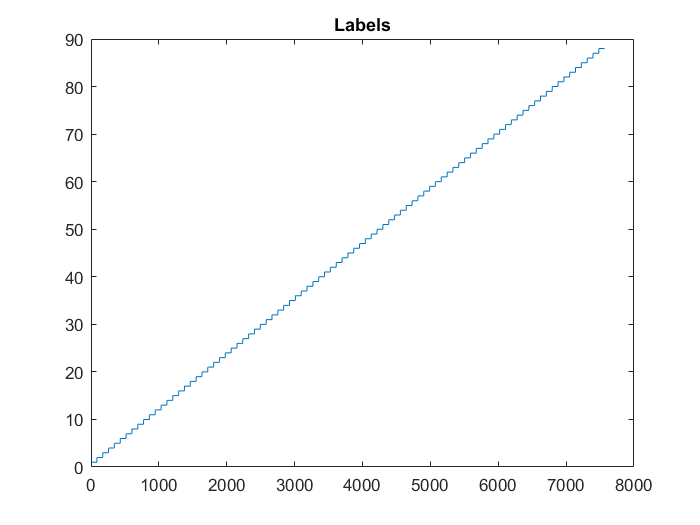


figure
plot(Y)
title("Labels")

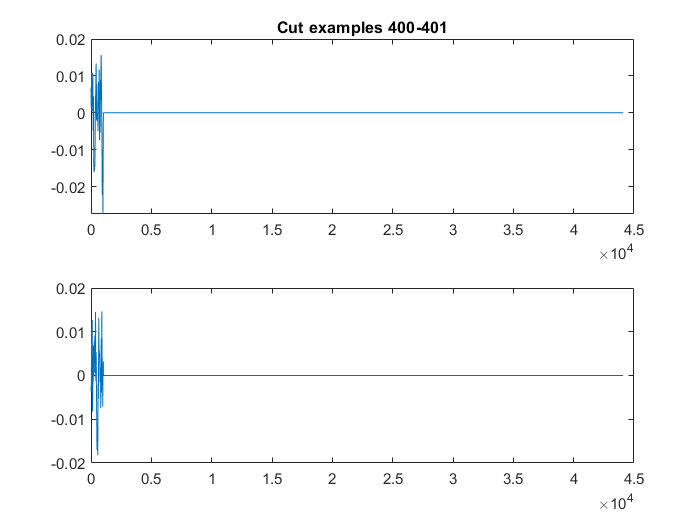


figure
subplot(2,1,1)
plot(X(400,:))
title("Cut examples 400-401")
subplot(2,1,2)
plot(X(401,:))

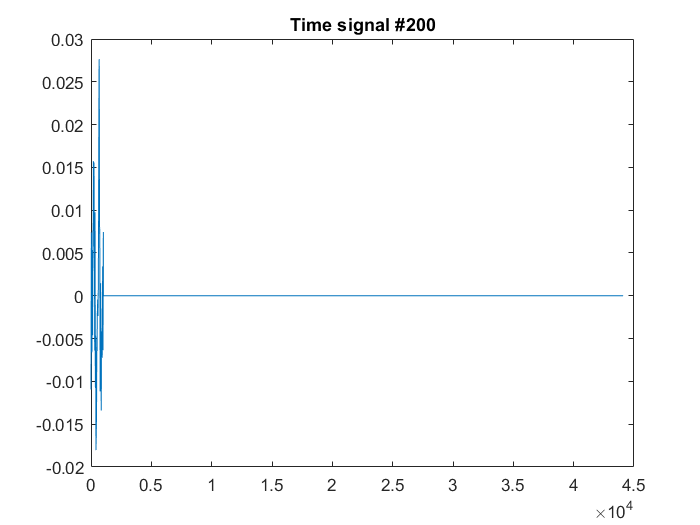


cv = cvpartition(Y,'HoldOut',0.30);
trainInds = training(cv);
testInds = test(cv);

XTrain = X(trainInds,:);
YTrain = Y(trainInds);
XTest = X(testInds,:);
YTest = Y(testInds);

clear X

[STest, MTest] = size(XTest);
[STrain, MTrain] = size(XTrain);

vtest = floor(1:MTest/ds);
vtrain = floor(1:MTrain/ds);

XTest_ds = zeros([STest, length(vtest)]);
XTrain_ds = zeros([STrain, length(vtrain)]);

% Get Spectrum. There is no need to get whole spectrum, It can be divided
% by half or more. ds - specifies how spectrum will be divided.
XTest_spec = abs(fft(XTest'))';
XTrain_spec = abs(fft(XTrain'))';

% Get only one part of spectrum, only important samples
XTest_ds(:, vtest) = XTest_spec(:, vtest);
XTrain_ds(:, vtest) = XTrain_spec(:, vtest);

figure
plot(XTest(200, :))
title("Time signal #200")

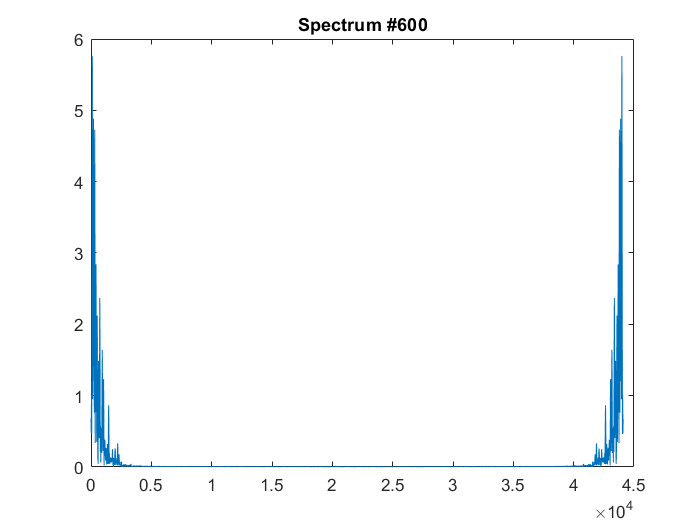


figure
plot(XTest_spec(600, :))
title("Spectrum #600")

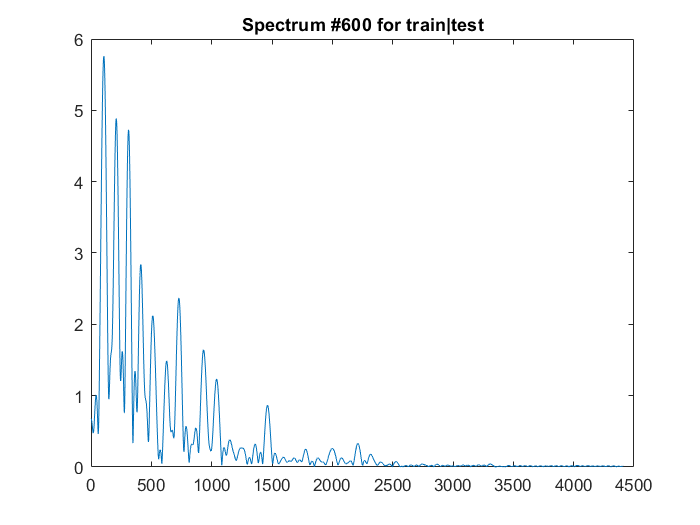


figure
plot(XTest_ds(600, :))
title("Spectrum #600 for train|test")

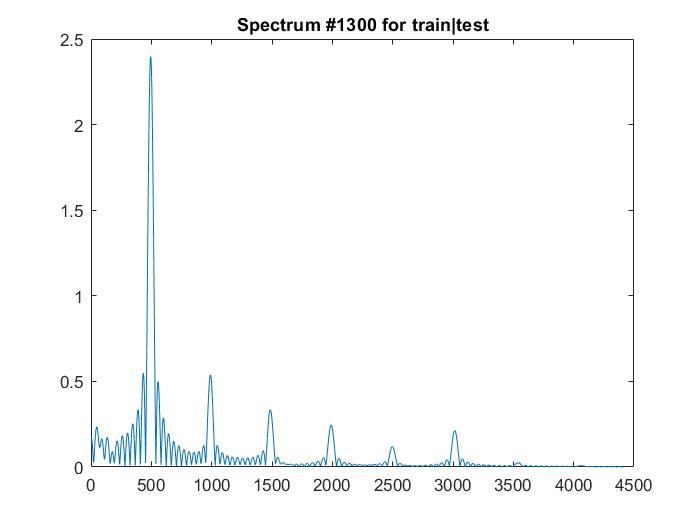


figure
plot(XTest_ds(1300, :))
title("Spectrum #1300 for train|test")

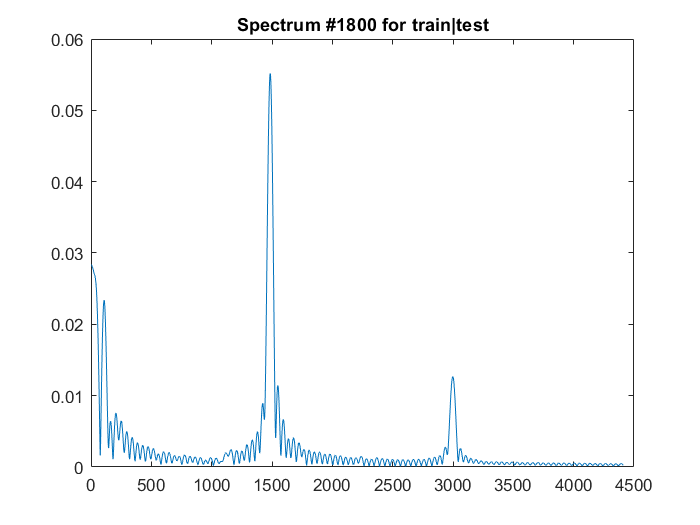


figure
plot(XTest_ds(1800, :))
title("Spectrum #1800 for train|test")


clear XTrain XTest XTest_spec XTrain_spec

Тестирую

% Если добавить нули во времени - психует и говорит что не понимает как ему
% считать с нулевой дисперсией

% Mdl = fitcnb(XTrain,YTrain);
% label = predict(Mdl,XTest);
% table(YTest,label,'VariableNames',...
%     {'TrueLabel','PredictedLabel'})
% 
% figure
% plot(label)
% hold on
% plot(YTest)
% title('Using time signal')

tic
Mdl_freq = fitcnb(XTrain_ds,YTrain);
label = predict(Mdl_freq,XTest_ds);
% table(YTest,label,'VariableNames',...
%     {'TrueLabel','PredictedLabel'})
toc

Elapsed time is 61.353410 seconds.


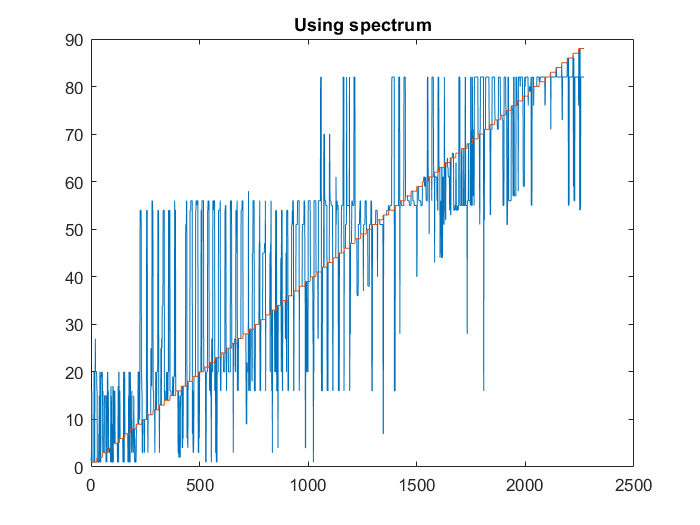


figure
plot(label)
hold on
plot(YTest)
title('Using spectrum')



p = ones([length(label), 1]);
for i = 1:length(p)
    if YTest(i) == label(i)
        p(i) = 0;
    end
end
errors = sum(p)/length(p)

errors = 0.6467

#### Вычислить ошибку модели (займет много времени)

clear all
close all
path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);

clear y

NOTES = 88;

NFFT = 1024;            % Кол-во отчетов для вырезки
N_zero = Fs - NFFT;     % Кол-во нулей после вырезки. Я буде для частотного шага 1Гц
N = floor(2/(NFFT/Fs)); % Количество вырезок за 2 секунды
N_row = N;
ds = 10;                % В сколько раз уменьшить спектр. Минимум 2 - нормально

errors = zeros([10, 1]);

tic
for q = 1:10
    
    data = reshape(z,4*Fs,[]);  % Каждая нота отдельно
    data = data(1:N*NFFT, :);   % Каждая нота отдельно Без нулей
    
    Y = zeros(N_row*NOTES, 1);
    X = zeros([N_row*NOTES, NFFT+N_zero]);
    
    for k=1:NOTES
        
        N1 = N * (k-1) + 1;
        N2 = N1 + N - 1;
        
        notes = reshape(data(:,k),1024,[])';
        
        X(N1:N2, 1:NFFT) = notes;
        Y(N1:N2) = k;
        
    end
    
    cv = cvpartition(Y,'HoldOut',0.30);
    trainInds = training(cv);
    testInds = test(cv);
    
    XTrain = X(trainInds,:);
    YTrain = Y(trainInds);
    XTest = X(testInds,:);
    YTest = Y(testInds);
    
    clear X
    
    [STest, MTest] = size(XTest);
    [STrain, MTrain] = size(XTrain);
    
    vtest = floor(1:MTest/ds);
    vtrain = floor(1:MTrain/ds);
    
    XTest_ds = zeros([STest, length(vtest)]);
    XTrain_ds = zeros([STrain, length(vtrain)]);
    
    % Get Spectrum. There is no need to get whole spectrum, It can be divided
    % by half or more. ds - specifies how spectrum will be divided.
    XTest_spec = abs(fft(XTest'))';
    XTrain_spec = abs(fft(XTrain'))';
    
    % Get only one part of spectrum, only important samples
    XTest_ds(:, vtest) = XTest_spec(:, vtest);
    XTrain_ds(:, vtest) = XTrain_spec(:, vtest);
    
    clear XTrain XTest XTest_spec XTrain_spec
    
    Mdl_freq = fitcnb(XTrain_ds,YTrain);
    label = predict(Mdl_freq,XTest_ds);

    p = ones([length(label), 1]);
    for i = 1:length(p)
        if YTest(i) == label(i)
            p(i) = 0;
        end
    end
    errors(q) = sum(p)/length(p);
end

errors =     0.6722
         0
         0
         0
         0
         0
         0
         0
         0
         0


errors =     0.6722
    0.6577
         0
         0
         0
         0
         0
         0
         0
         0


errors =     0.6722
    0.6577
    0.6524
         0
         0
         0
         0
         0
         0
         0


errors =     0.6722
    0.6577
    0.6524
    0.6568
         0
         0
         0
         0
         0
         0


errors =     0.6722
    0.6577
    0.6524
    0.6568
    0.6441
         0
         0
         0
         0
         0


errors =     0.6722
    0.6577
    0.6524
    0.6568
    0.6441
    0.6626
         0
         0
         0
         0


errors =     0.6722
    0.6577
    0.6524
    0.6568
    0.6441
    0.6626
    0.6414
         0
         0
         0


errors =     0.6722
    0.6577
    0.6524
    0.6568
    0.6441
    0.6626
    0.6414
    0.6515
         0
         0


errors =     0.6722
    0.6577
    0.6524
    0.6568
    0.6441
    0.6626
    0.6414
    0.6515
    0.6670
         0


errors =     0.6722
    0.6577
    0.6524
    0.6568
    0.6441
    0.6626
    0.6414
    0.6515
    0.6670
    0.6705


errors =     0.6722
    0.6577
    0.6524
    0.6568
    0.6441
    0.6626
    0.6414
    0.6515
    0.6670
    0.6705


errors =     0.6722
    0.6577
    0.6524
    0.6568
    0.6441
    0.6626
    0.6414
    0.6515
    0.6670
    0.6705


errors =     0.6722
    0.6577
    0.6524
    0.6568
    0.6441
    0.6626
    0.6414
    0.6515
    0.6670
    0.6705


errors =     0.6722
    0.6577
    0.6524
    0.6568
    0.6441
    0.6626
    0.6414
    0.6515
    0.6670
    0.6705


errors =     0.6722
    0.6577
    0.6524
    0.6568
    0.6441
    0.6626
    0.6414
    0.6515
    0.6670
    0.6705


toc

Elapsed time is 917.537069 seconds.


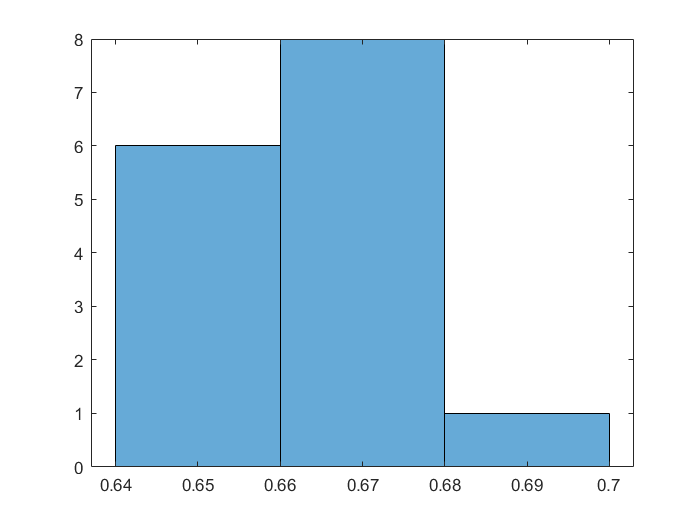


histogram(errors)

mean_e = mean(errors)

mean_e = 0.6623

std_e = std(errors)

std_e = 0.0118